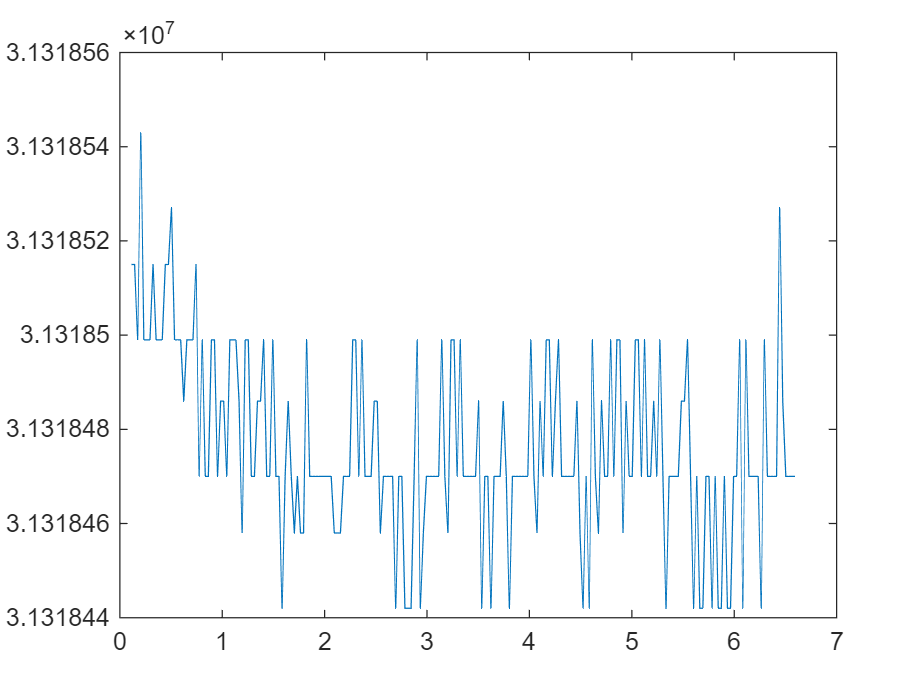

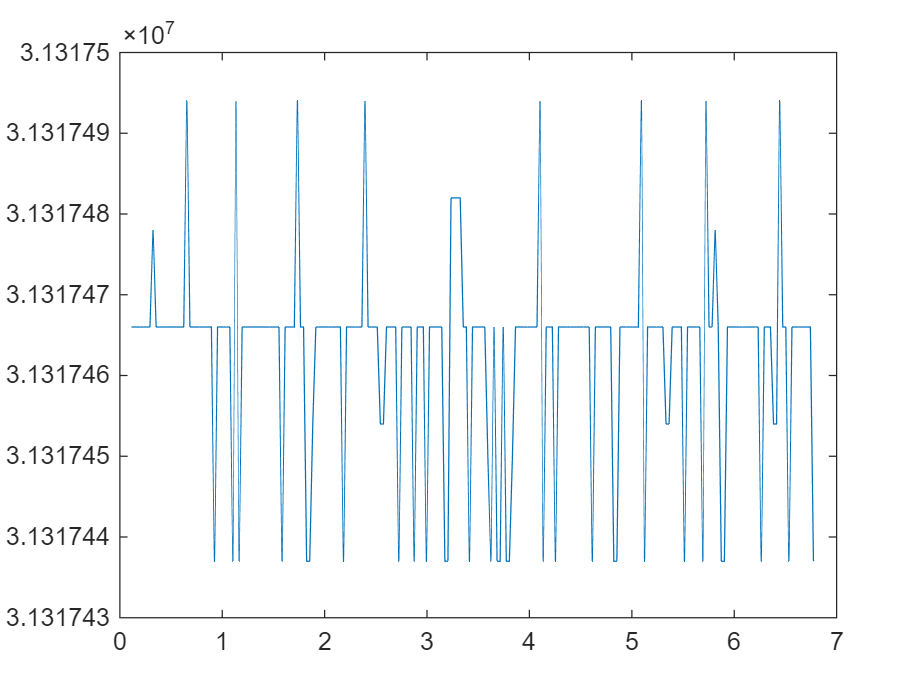

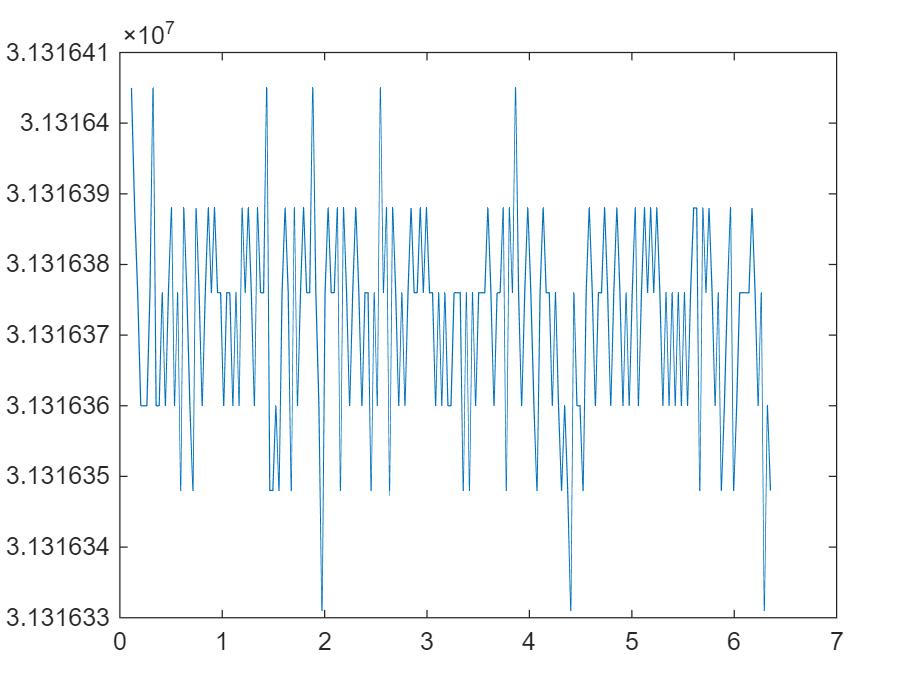

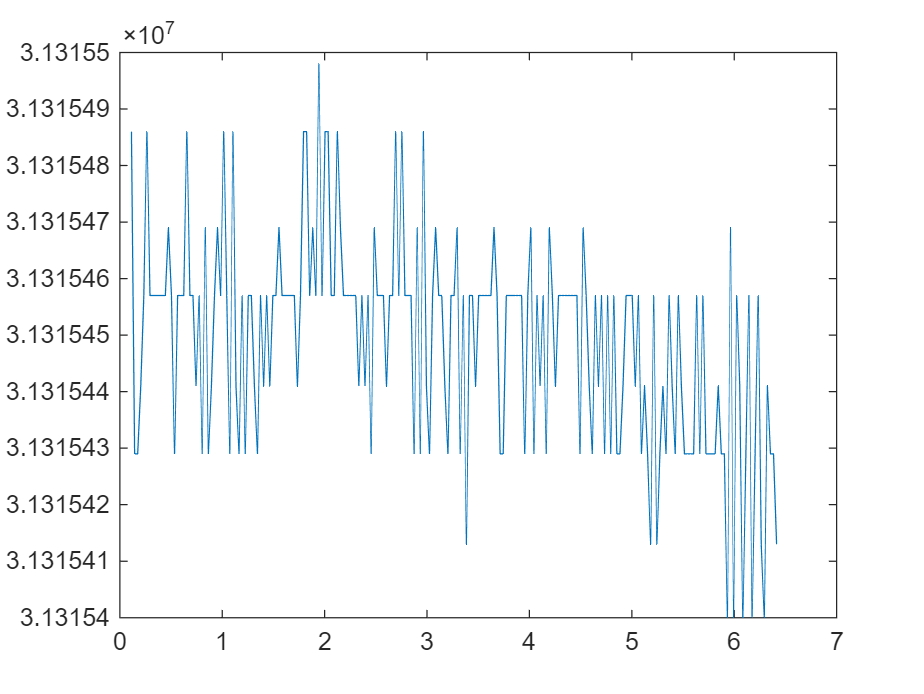

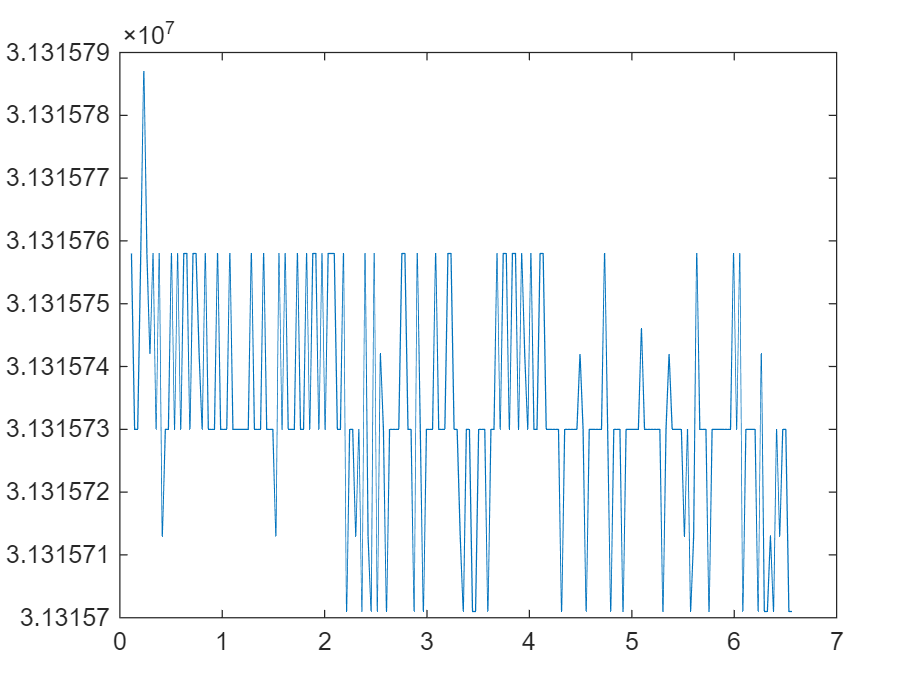

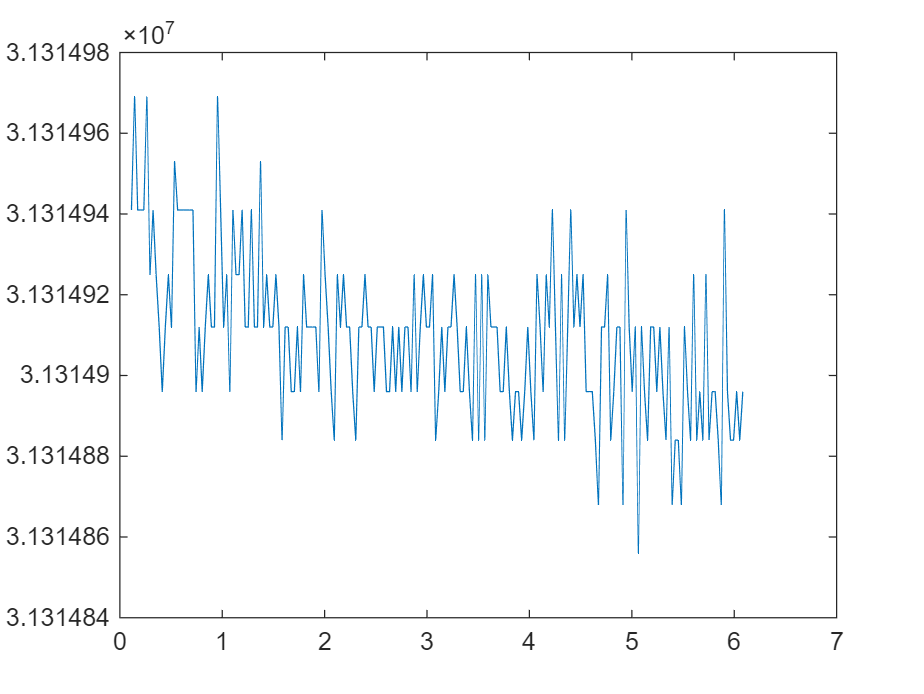

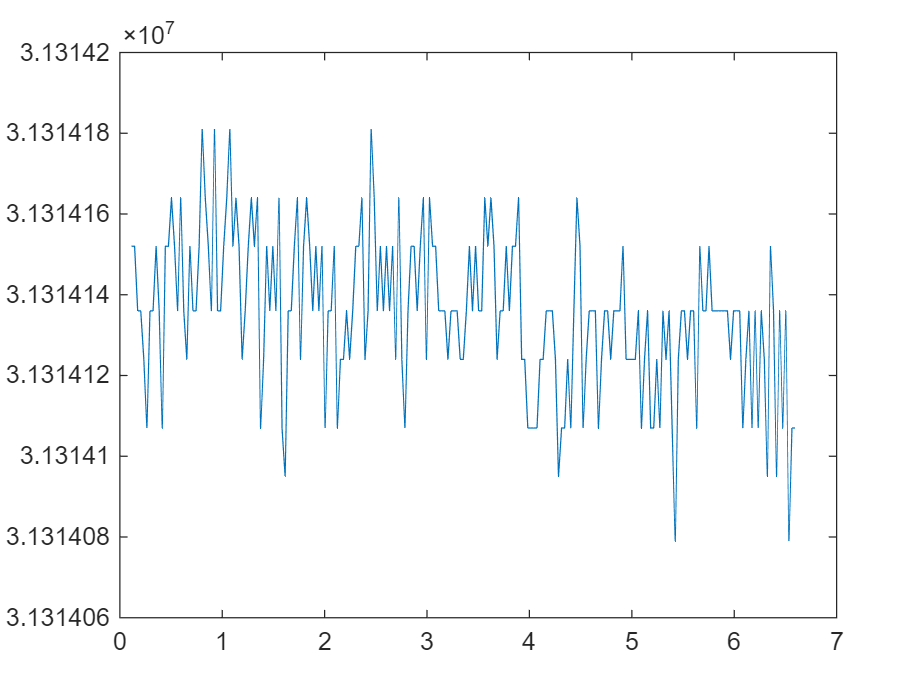

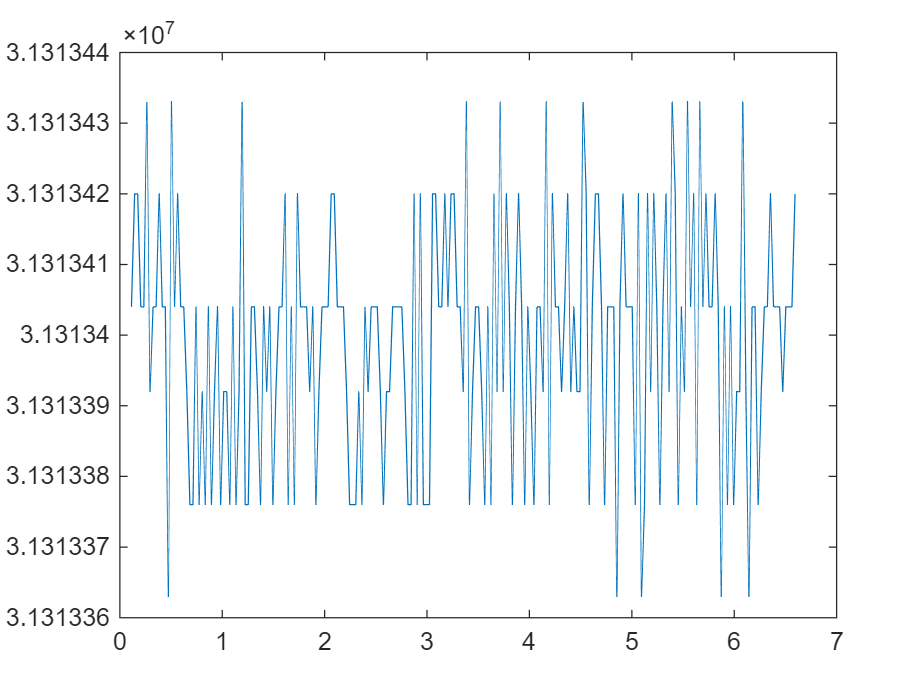

weight = 0:1:11;

weight_mag = zeros(size(weight));

for i = 1:length(weight)

    filename = strcat('weight_',num2str(weight(i)),'g.csv');

    raw_data = readtable(filename,'Delimiter',',');

    % Take care of header chunk
    raw_time = raw_data{:,1};
    [row, ~] = find(isnan(raw_time));

    if ~isempty(row)
        % double check to make sure nan is from the header instead of data
        if (row(end) - row(1) + 1) == length(row)

            raw_data = raw_data(row(end)+1:end,:); % clip header
        end
    end
    raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

    % Raw time & data
    time = raw_data{:,1}./1000; % in seconds
    data = raw_data{:,2};

    % Show raw data plot
    figure;
    plot(time, data)

    time_difference = time(2:end) - time(1:end-1);
    ts = mean(time_difference);
    std_ts = std(time_difference);

    fs = 1/ts;

    rs_time = time(1):ts:time(end);

    rs_data = interp1(time,data,rs_time,'spline');

    data2save = mean(data);

    weight_mag(i) = data2save;

end

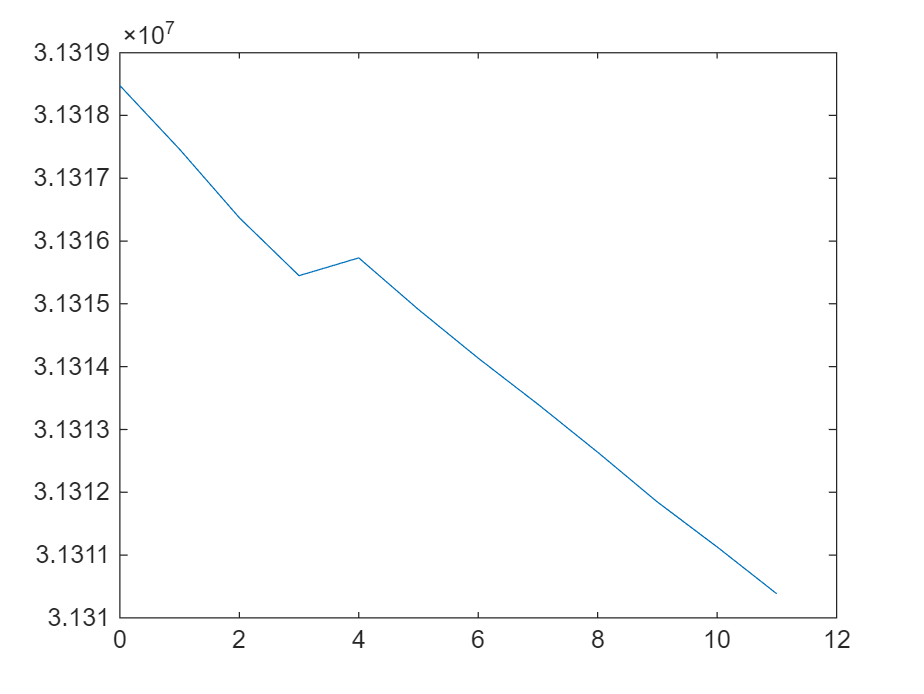



figure;
plot(weight,weight_mag)